%ProcessGnssMeasScript.m, script to read GnssLogger output, compute and plot:
% pseudoranges, C/No, and weighted least squares PVT solution
%
% you can run the data in pseudoranges log files provided for you: 
% prFileName = 'gnss_log_2020_08_07_15_09_27.txt'; %with duty cycling, no carrier phase


close all;
clear all;


GroundTruth=[
    22.576062252004220  113.9363809520042;
    22.5760482040084	113.936366904008;
    22.5760335468354	113.936352246835;
    22.5760194988397	113.936338198840;
    22.5759907936709	113.936309493671;
    22.5760054508439	113.936324150844;
    22.5759767456751	113.936295445675;
    22.5759767456751	113.936295445675;
    22.5759914028481	113.936310102848;
    22.5759626976793	113.936281397679;
    22.5759773548523	113.936296054852;
    22.5759486496835	113.936267349684;
];

FileNameList = [
    'gnss_log_2020_08_07_03_36_36.txt';
    'gnss_log_2020_08_07_03_46_58.txt';
    'gnss_log_2020_08_07_03_37_09.txt';
    'gnss_log_2020_08_07_03_47_20.txt';
    'gnss_log_2020_08_07_03_20_59.txt';
    'gnss_log_2020_08_07_03_28_19.txt';
    'gnss_log_2020_08_07_03_21_45.txt';
    'gnss_log_2020_08_07_03_28_43.txt';
    'gnss_log_2020_08_07_03_14_16.txt';
    'gnss_log_2020_08_07_03_14_52.txt';
    'gnss_log_2020_08_07_03_05_34.txt';
    'gnss_log_2020_08_07_03_06_15.txt';
    'gnss_log_2020_08_07_03_02_21.txt';
    'gnss_log_2020_08_07_03_02_38.txt';
    'gnss_log_2020_08_07_02_58_59.txt';
    'gnss_log_2020_08_07_03_55_51.txt';
    'gnss_log_2020_08_07_02_59_09.txt';
    'gnss_log_2020_08_07_03_56_04.txt';
];
% check the FileDir
% set workpath
cd D:\Project\lab-gpsbackscatter\opensource\
FileDir = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\';
GpsEphDir = FileDir;
% CaseNum = 12;
CaseNum = length(GroundTruth(:,1))

CaseNum = 12

FileNum = length(FileNameList(:,1))

FileNum = 18


iCase = 1;
iFile = 1;

jDataNum = 1; jBKSNum = 2; 
jValidNum = 3; jValidRate = 4; 
jBKSAver = 5; jBKSMin = 6; jBKSMax = 7; jBKSMid = 8; jBKSStd = 9;
jPickNum = 10; jPickRate = 11; jPVRate = 12; 
jPickAver = 13; jPickMin = 14; jPickMax = 15; jPickMid = 16; jPickStd = 17;

jNBKSValidNum = 18; jNBKSValidRate = 19; 
jNBKSAver = 20; jNBKSMin = 21; jNBKSMax = 22; jNBKSMid = 23; jNBKSStd = 24;

ParaNum = 24;

Result = zeros(ParaNum, FileNum);

% make sure your work path is project path !
for iFile=1:FileNum
while iCase <= CaseNum
    % save data from GnssLogger App, and edit dirName and prFileName appropriately
    %dirName = 'put the full path for your directory here';
    dirName = [FileDir num2str(iCase)];
    %prFileName = 'put the pseuoranges log file name here';
    prFileName = FileNameList(iFile,:);
    FilePath = [dirName '\' prFileName]
    if ~exist(FilePath,'file')
       iCase = iCase + 1
    else
        dirName = [FileDir num2str(iCase)]
        prFileName = FileNameList(iFile,:)
        break
    end
end

param.llaTrueDegDegM = [GroundTruth(iCase, :) 0];


FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_36_36.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1'

prFileName = 'gnss_log_2020_08_07_03_36_36.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_46_58.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1'

prFileName = 'gnss_log_2020_08_07_03_46_58.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_37_09.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_37_09.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2'

prFileName = 'gnss_log_2020_08_07_03_37_09.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_47_20.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_47_20.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2'

prFileName = 'gnss_log_2020_08_07_03_47_20.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_20_59.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_20_59.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_20_59.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3'

prFileName = 'gnss_log_2020_08_07_03_20_59.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_28_19.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_28_19.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_28_19.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3'

prFileName = 'gnss_log_2020_08_07_03_28_19.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_21_45.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_21_45.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_21_45.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_21_45.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4'

prFileName = 'gnss_log_2020_08_07_03_21_45.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_28_43.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_28_43.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_28_43.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_28_43.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4'

prFileName = 'gnss_log_2020_08_07_03_28_43.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_14_16.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_14_16.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_14_16.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_14_16.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_03_14_16.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5'

prFileName = 'gnss_log_2020_08_07_03_14_16.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_14_52.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_14_52.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_14_52.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_14_52.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_03_14_52.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_03_14_52.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6'

prFileName = 'gnss_log_2020_08_07_03_14_52.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_05_34.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_05_34.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_05_34.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_05_34.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_03_05_34.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_03_05_34.txt'

iCase = 7

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7\gnss_log_2020_08_07_03_05_34.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7'

prFileName = 'gnss_log_2020_08_07_03_05_34.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_06_15.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_06_15.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_06_15.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_06_15.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_03_06_15.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_03_06_15.txt'

iCase = 7

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7\gnss_log_2020_08_07_03_06_15.txt'

iCase = 8

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8\gnss_log_2020_08_07_03_06_15.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8'

prFileName = 'gnss_log_2020_08_07_03_06_15.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_02_21.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_02_21.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_02_21.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_02_21.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_03_02_21.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_03_02_21.txt'

iCase = 7

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7\gnss_log_2020_08_07_03_02_21.txt'

iCase = 8

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8\gnss_log_2020_08_07_03_02_21.txt'

iCase = 9

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\9\gnss_log_2020_08_07_03_02_21.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\9'

prFileName = 'gnss_log_2020_08_07_03_02_21.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_02_38.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_02_38.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_02_38.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_02_38.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_03_02_38.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_03_02_38.txt'

iCase = 7

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7\gnss_log_2020_08_07_03_02_38.txt'

iCase = 8

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8\gnss_log_2020_08_07_03_02_38.txt'

iCase = 9

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\9\gnss_log_2020_08_07_03_02_38.txt'

iCase = 10

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\10\gnss_log_2020_08_07_03_02_38.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\10'

prFileName = 'gnss_log_2020_08_07_03_02_38.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_02_58_59.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_02_58_59.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_02_58_59.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_02_58_59.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_02_58_59.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_02_58_59.txt'

iCase = 7

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7\gnss_log_2020_08_07_02_58_59.txt'

iCase = 8

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8\gnss_log_2020_08_07_02_58_59.txt'

iCase = 9

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\9\gnss_log_2020_08_07_02_58_59.txt'

iCase = 10

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\10\gnss_log_2020_08_07_02_58_59.txt'

iCase = 11

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\11\gnss_log_2020_08_07_02_58_59.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\11'

prFileName = 'gnss_log_2020_08_07_02_58_59.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_55_51.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_55_51.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_55_51.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_55_51.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_03_55_51.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_03_55_51.txt'

iCase = 7

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7\gnss_log_2020_08_07_03_55_51.txt'

iCase = 8

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8\gnss_log_2020_08_07_03_55_51.txt'

iCase = 9

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\9\gnss_log_2020_08_07_03_55_51.txt'

iCase = 10

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\10\gnss_log_2020_08_07_03_55_51.txt'

iCase = 11

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\11\gnss_log_2020_08_07_03_55_51.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\11'

prFileName = 'gnss_log_2020_08_07_03_55_51.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_02_59_09.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_02_59_09.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_02_59_09.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_02_59_09.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_02_59_09.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_02_59_09.txt'

iCase = 7

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7\gnss_log_2020_08_07_02_59_09.txt'

iCase = 8

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8\gnss_log_2020_08_07_02_59_09.txt'

iCase = 9

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\9\gnss_log_2020_08_07_02_59_09.txt'

iCase = 10

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\10\gnss_log_2020_08_07_02_59_09.txt'

iCase = 11

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\11\gnss_log_2020_08_07_02_59_09.txt'

iCase = 12

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\12\gnss_log_2020_08_07_02_59_09.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\12'

prFileName = 'gnss_log_2020_08_07_02_59_09.txt'

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1\gnss_log_2020_08_07_03_56_04.txt'

iCase = 2

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2\gnss_log_2020_08_07_03_56_04.txt'

iCase = 3

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3\gnss_log_2020_08_07_03_56_04.txt'

iCase = 4

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4\gnss_log_2020_08_07_03_56_04.txt'

iCase = 5

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5\gnss_log_2020_08_07_03_56_04.txt'

iCase = 6

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6\gnss_log_2020_08_07_03_56_04.txt'

iCase = 7

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7\gnss_log_2020_08_07_03_56_04.txt'

iCase = 8

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8\gnss_log_2020_08_07_03_56_04.txt'

iCase = 9

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\9\gnss_log_2020_08_07_03_56_04.txt'

iCase = 10

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\10\gnss_log_2020_08_07_03_56_04.txt'

iCase = 11

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\11\gnss_log_2020_08_07_03_56_04.txt'

iCase = 12

FilePath = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\12\gnss_log_2020_08_07_03_56_04.txt'

dirName = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\12'

prFileName = 'gnss_log_2020_08_07_03_56_04.txt'

%% parameters
%param.llaTrueDegDegM = [];
%enter true WGS84 lla, if you know it:
% param.llaTrueDegDegM = [37.422578, -122.081678, -28];%Charleston Park Test Site

%% Set the data filter and Read log file
dataFilter = SetDataFilter;
[gnssRaw,gnssAnalysis] = ReadGnssLogger(dirName,prFileName,dataFilter);


Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1/gnss_log_2020_08_07_03_36_36.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\1/gnss_log_2020_08_07_03_46_58.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2/gnss_log_2020_08_07_03_37_09.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\2/gnss_log_2020_08_07_03_47_20.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3/gnss_log_2020_08_07_03_20_59.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\3/gnss_log_2020_08_07_03_28_19.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4/gnss_log_2020_08_07_03_21_45.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\4/gnss_log_2020_08_07_03_28_43.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\5/gnss_log_2020_08_07_03_14_16.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\6/gnss_log_2020_08_07_03_14_52.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\7/gnss_log_2020_08_07_03_05_34.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\8/gnss_log_2020_08_07_03_06_15.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\9/gnss_log_2020_08_07_03_02_21.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\10/gnss_log_2020_08_07_03_02_38.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\11/gnss_log_2020_08_07_02_58_59.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\11/gnss_log_2020_08_07_03_55_51.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\12/gnss_log_2020_08_07_02_59_09.txt



Reading file ..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\12/gnss_log_2020_08_07_03_56_04.txt


if isempty(gnssRaw), return, end

%% Get online ephemeris from Nasa ftp, first compute UTC Time from gnssRaw:
fctSeconds = 1e-3*double(gnssRaw.allRxMillis(end));
utcTime = Gps2Utc([],fctSeconds);
% allGpsEph = GetNasaHourlyEphemeris(utcTime,dirName);
allGpsEph = GetNasaHourlyEphemeris(utcTime,GpsEphDir);

Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


Reading GPS ephemeris from 'hour2190.20n' file in local directory
..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\


if isempty(allGpsEph), return, end


Removed 11 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Removed 64 bad meas inside ProcessGnssMeas>FilterValid because:
towUnc > 500 ns



Removed 6 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Removed 8 bad meas inside ProcessGnssMeas>FilterValid because:
towUnc > 500 ns
prrUnc > 10 m/s



Removed 32 bad meas inside ProcessGnssMeas>FilterValid because:
towUnc > 500 ns
prrUnc > 10 m/s



Removed 1 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Removed 63 bad meas inside ProcessGnssMeas>FilterValid because:
towUnc > 500 ns
prrUnc > 10 m/s



Removed 3 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Removed 1 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Removed 19 bad meas inside ProcessGnssMeas>FilterValid because:
towUnc > 500 ns



Removed 1 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s


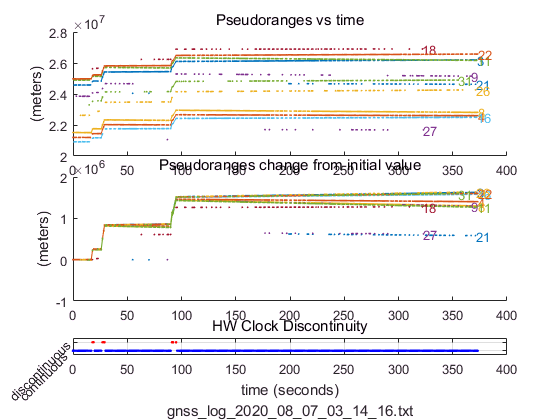

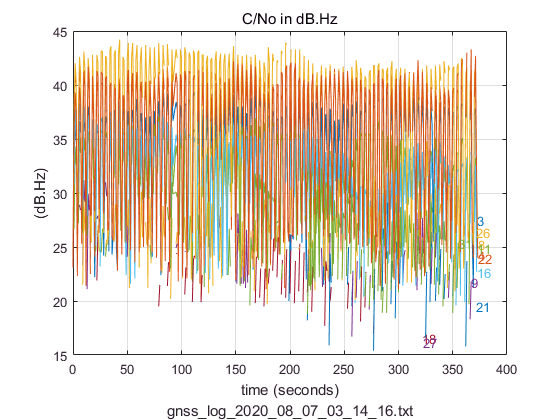

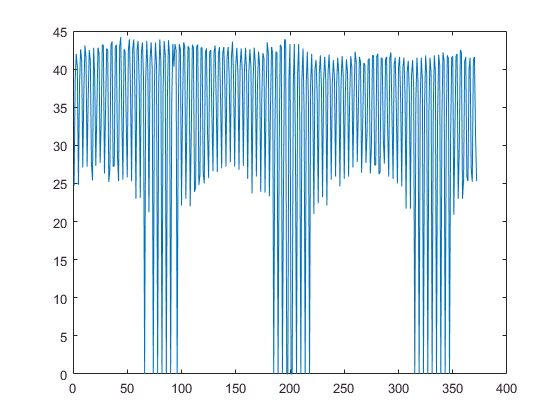

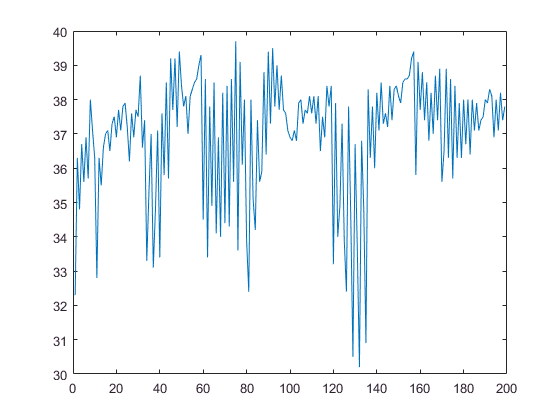

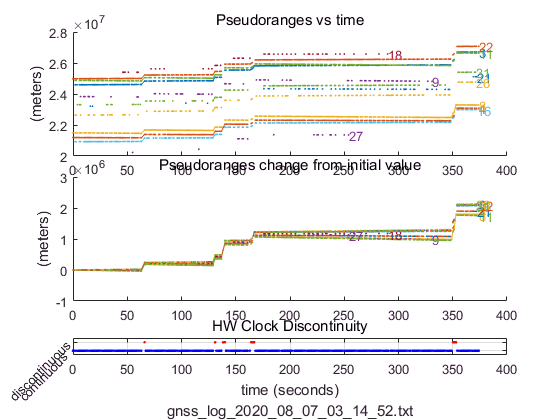

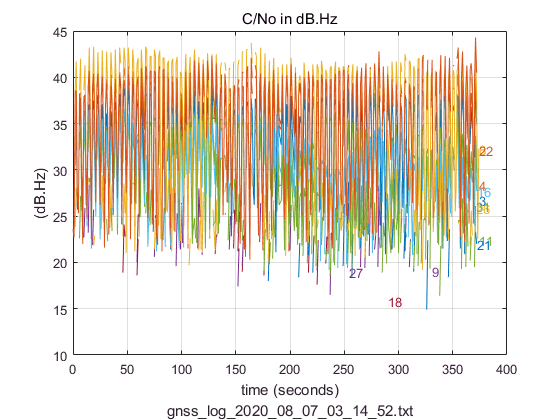

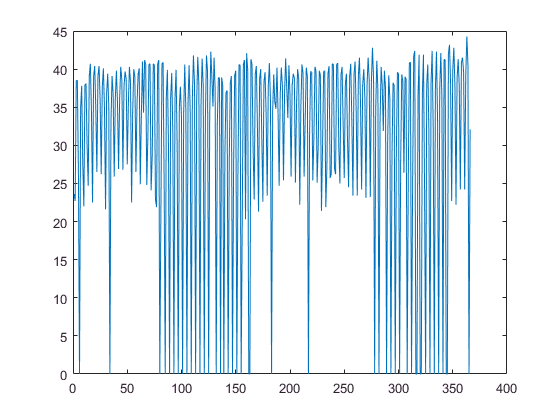

%% process raw measurements, compute pseudoranges:
% [gnssMeas] = ProcessGnssMeas(gnssRaw);
% [gnssMeas_BKS, gnssRaw_BKS]=Seprate(gnssRaw,gnssMeas,prFileName);

if ~exist([dirName '\' 'gnssMean.mat'], 'file')
    [gnssMeas]= ProcessGnssMeasForBackscatter(gnssRaw);
    [gnssMeas_BKS, gnssMeas_NBKS]=Seprate(gnssRaw,gnssMeas,prFileName);
    save( [dirName '\' 'gnssMean.mat'],'gnssMeas', 'gnssMeas_BKS', 'gnssMeas_NBKS');
else
    load([dirName '\' 'gnssMean.mat'],'gnssMeas', 'gnssMeas_BKS', 'gnssMeas_NBKS');
end



Result(jDataNum,iFile) = length(gnssMeas.FctSeconds(:,1));
Result(jBKSNum,iFile) = length(gnssMeas_BKS.FctSeconds(:,1));

% [gnssMeasBackscattered]=gnssMeasSeprate(gnssMeas,prFileName);
% %% plot pseudoranges and pseudorange rates
% h1 = figure;
% [colors] = PlotPseudoranges(gnssMeas,prFileName);
% h2 = figure;
% PlotPseudorangeRates(gnssMeas,prFileName,colors);
% h3 = figure;
% PlotCno(gnssMeas,prFileName,colors);

## 找到最近时间星历

% %% 卫星位置计算
% % SatPvt=CalcSatCoordination(gnssMeas);
% NumberNanoSecondsWeek=604800e9;
% %括号里面取对应第i位
% WN=floor(double(-gnssRaw.FullBiasNanos(1))/NumberNanoSecondsWeek);
% tRxGnss=double(gnssRaw.TimeNanos(1)) + double(gnssRaw.TimeOffsetNanos(1))-(double(gnssRaw.FullBiasNanos(1))+gnssRaw.BiasNanos(1));
% FullBiasNanos=double(gnssRaw.FullBiasNanos);
% weekNumberNanos=(floor((-FullBiasNanos(1))/NumberNanoSecondsWeek))*NumberNanoSecondsWeek;
% TOW=(tRxGnss-double(weekNumberNanos))*1e-9;
% % 查找匹配项
% Svid=3;
% % JDay=JulianDay(utcTime);
% % WeekDay=cal2wd([2020 8 6]); weekday(D,DayForm)
% 
% % GPS时间转换成UTC秒数目
% D=[num2str(utcTime(2)),'-',num2str(utcTime(3)),'-',num2str(utcTime(1))];
% [DayNumber,DayName] = weekday(D);
% UTCSeconds=(DayNumber-1)*24*60*60+18;%包含润秒的总秒数18秒
% 
% % UTCSeconds=345618;%包含润秒的总秒数
% % GPS时间转换成UTC秒数目
% iEph = find(([allGpsEph.PRN]'==Svid)&([allGpsEph.Toc]'==UTCSeconds));
% GpsEph=allGpsEph(iEph);
% 
% 
%     position=SatPosition(GpsEph(1),TOW(1),WN)

% 
% % gpsPvt = GpsWlsPvt(gnssMeasBackscattered,allGpsEph);
% N = length(gnssMeas_BKS.FctSeconds);
% for i=1:N
%     iValid = find(isfinite(gnssMeas_BKS.PrM(i,:))); %index into valid svid
%     svid    = gnssMeas_BKS.Svid(iValid)';
%     
%     [gpsEph,iSv] = ClosestGpsEph(allGpsEph,svid,gnssMeas_BKS.FctSeconds(i));
%     svid = svid(iSv); %svid for which we have ephemeris
%     numSvs = length(svid); %number of satellites this epoch
%     gpsPvt_BKS.numSvs(i) = numSvs;
%     if numSvs<4
%         continue;%skip to next epoch
%     end
% %     gpsPvt_BKS.position=SatPosition(allGpsEph(1),TOW(1),WN)
% end
% 

## 计算卫星实际位置

## Google Solution Pvt

%% compute WLS position and velocity
gpsPvt = GpsWlsPvt(gnssMeas,allGpsEph);
gpsPvt_BKS = GpsWlsPvt(gnssMeas_BKS,allGpsEph);
gpsPvt_NBKS = GpsWlsPvt(gnssMeas_NBKS,allGpsEph);


%% plot Pvt results
% h4 = figure;
% ts = 'Raw Pseudoranges, Weighted Least Squares solution';
% PlotPvt(gpsPvt,prFileName,param.llaTrueDegDegM,ts); drawnow;
% h5 = figure;
% PlotPvtStates(gpsPvt,prFileName);

%% Plot Accumulated Delta Range 
if any(any(isfinite(gnssMeas.AdrM) & gnssMeas.AdrM~=0))
    [gnssMeas]= ProcessAdr(gnssMeas);
    h6 = figure;
    PlotAdr(gnssMeas,prFileName,colors);
    [adrResid]= GpsAdrResiduals(gnssMeas,allGpsEph,param.llaTrueDegDegM);drawnow
    h7 = figure;
    PlotAdrResids(adrResid,gnssMeas,prFileName,colors);
end

## 距离和误差计算 NBKS

% distance=distanceCountViaCoordinate(gpsPvt.allLlaDegDegM(:,1:2),b)
lenNBackscatted = length(gpsPvt_NBKS.allLlaDegDegM(:,1))

lenNBackscatted = 266

lenNBackscatted = 266

lenNBackscatted = 259

lenNBackscatted = 259

lenNBackscatted = 184

lenNBackscatted = 184

lenNBackscatted = 122

lenNBackscatted = 122

lenNBackscatted = 173

lenNBackscatted = 160

lenNBackscatted = 202

lenNBackscatted = 135

lenNBackscatted = 78

lenNBackscatted = 83

lenNBackscatted = 77

lenNBackscatted = 77

lenNBackscatted = 49

lenNBackscatted = 49

distance = zeros(lenNBackscatted,1);
cntDisNan = 0;
cntDis = 0;
for i = 1:length(gpsPvt_NBKS.allLlaDegDegM(:,1))
    if isnan(gpsPvt_NBKS.allLlaDegDegM(i,1)) 
        cntDisNan = cntDisNan + 1;
    else
        cntDis = cntDis + 1;
        distance(cntDis)=distanceCountViaCoordinate(gpsPvt_NBKS.allLlaDegDegM(i,1:2), GroundTruth(iCase,:));
        distance_origin(i) = distance(cntDis);
    end
end

% save('dis_dir.mat','distance');
ValidRate = cntDis / lenNBackscatted;
if cntDis > 0 
    disAver = mean(distance(:)) * lenNBackscatted / cntDis;
    disMin = min(distance(1:cntDis));
    disMax = max(distance(1:cntDis));
    disMid = median(distance(1:cntDis));
    disStd = std(distance(1:cntDis));
else
    disAver = 0;
    disMin = 0;
    disMax = 0;
    disMid = 0;
    disStd = 0;
end


Result(jNBKSValidNum,iFile) = cntDis;
Result(jNBKSValidRate,iFile) = ValidRate;
Result(jNBKSAver,iFile) = disAver;
Result(jNBKSMin,iFile) = disMin;
Result(jNBKSMax,iFile) = disMax;
Result(jNBKSMid,iFile) = disMid;
Result(jNBKSStd,iFile) = disStd;

% figure
% plot(distance(1:cntDis))
% hold on
% plot(disAver .* ones(cntDis, 1))

## 距离和误差计算 BKS

% distance=distanceCountViaCoordinate(gpsPvt.allLlaDegDegM(:,1:2),b)
lenBackscatted = length(gpsPvt_BKS.allLlaDegDegM(:,1))

lenBackscatted = 339

lenBackscatted = 339

lenBackscatted = 335

lenBackscatted = 335

lenBackscatted = 231

lenBackscatted = 231

lenBackscatted = 191

lenBackscatted = 191

lenBackscatted = 199

lenBackscatted = 206

lenBackscatted = 256

lenBackscatted = 227

lenBackscatted = 93

lenBackscatted = 104

lenBackscatted = 103

lenBackscatted = 103

lenBackscatted = 106

lenBackscatted = 106

distance = zeros(lenBackscatted,1);
cntDisNan = 0;
cntDis = 0;
for i = 1:length(gpsPvt_BKS.allLlaDegDegM(:,1))
    if isnan(gpsPvt_BKS.allLlaDegDegM(i,1)) 
        cntDisNan = cntDisNan + 1;
    else
        cntDis = cntDis + 1;
        distance(cntDis)=distanceCountViaCoordinate(gpsPvt_BKS.allLlaDegDegM(i,1:2), GroundTruth(iCase,:));
        distance_origin(i) = distance(cntDis);
    end
end

% save('dis_dir.mat','distance');
ValidRate = cntDis / lenBackscatted;
if cntDis > 0 
    disAver = mean(distance(:)) * lenBackscatted / cntDis;
    disMin = min(distance(1:cntDis));
    disMax = max(distance(1:cntDis));
    disMid = median(distance(1:cntDis));
    disStd = std(distance(1:cntDis));
else
    disAver = 0;
    disMin = 0;
    disMax = 0;
    disMid = 0;
    disStd = 0;
end


Result(jValidNum,iFile) = cntDis;
Result(jValidRate,iFile) = ValidRate;
Result(jBKSAver,iFile) = disAver;
Result(jBKSMin,iFile) = disMin;
Result(jBKSMax,iFile) = disMax;
Result(jBKSMid,iFile) = disMid;
Result(jBKSStd,iFile) = disStd;

% figure
% plot(distance(1:cntDis))
% hold on
% plot(disAver .* ones(cntDis, 1))

## 对比两个误差

% dis_bks = load('dis_bks.mat');
% load('pickUp.mat');
% 
% distance_all = zeros(length(pickUp),2);
% cntRegular = [1 1];
% for i=1:length(pickUp)
%    if pickUp(i)
%       distance_all(i,1) = dis_bks.distance(cntRegular(1));
%       cntRegular(1) = cntRegular(1) + 1;
%    else
%       distance_all(i,2) = distance_origin(cntRegular(2));
%       cntRegular(2) = cntRegular(2) + 1;
%    end
% end
% 
% figure
% plot(distance_all)


## 挑数据

iPick30 = find(distance(1:cntDis)<30);
len30 = length(iPick30)

len30 = 27

len30 = 27

len30 = 23

len30 = 23

len30 = 9

len30 = 9

len30 = 12

len30 = 12

len30 = 45

len30 = 53

len30 = 127

len30 = 118

len30 = 42

len30 = 30

len30 = 1

len30 = 1

len30 = 6

len30 = 6

PickRate = len30 / lenBackscatted

PickRate = 0.0796

PickRate = 0.0796

PickRate = 0.0687

PickRate = 0.0687

PickRate = 0.0390

PickRate = 0.0390

PickRate = 0.0628

PickRate = 0.0628

PickRate = 0.2261

PickRate = 0.2573

PickRate = 0.4961

PickRate = 0.5198

PickRate = 0.4516

PickRate = 0.2885

PickRate = 0.0097

PickRate = 0.0097

PickRate = 0.0566

PickRate = 0.0566

Rate_PV = PickRate / ValidRate

Rate_PV = 0.0796

Rate_PV = 0.0796

Rate_PV = 0.0687

Rate_PV = 0.0687

Rate_PV = 0.0390

Rate_PV = 0.0390

Rate_PV = 0.0628

Rate_PV = 0.0628

Rate_PV = 0.2261

Rate_PV = 0.2573

Rate_PV = 0.4961

Rate_PV = 0.5198

Rate_PV = 0.4516

Rate_PV = 0.2885

Rate_PV = 0.0097

Rate_PV = 0.0097

Rate_PV = 0.0566

Rate_PV = 0.0566

distance30 = distance(iPick30);

if len30 > 0
    disAver30 = mean(distance30(:));
    disMin = min(distance30);
    disMax = max(distance30);
    disMid = median(distance30);
    disStd = std(distance30);
else
    disAver30 = 0;
    disMin = 0;
    disMax = 0;
    disMid = 0;
    disStd = 0;
    
end


Result(jPickNum,iFile) = len30;
Result(jPickRate,iFile) = PickRate;
Result(jPVRate,iFile) = Rate_PV;
Result(jPickAver,iFile) = disAver30;
Result(jPickMin,iFile) = disMin;
Result(jPickMax,iFile) = disMax;
Result(jPickMid,iFile) = disMid;
Result(jPickStd,iFile) = disStd;

% figure
% plot(distance30)
% hold on
% plot(disAver30  .* ones(len30, 1) )

## 保存结果

iCase = 1;

%  return;
end
save([FileDir 'Result.mat'],'Result');

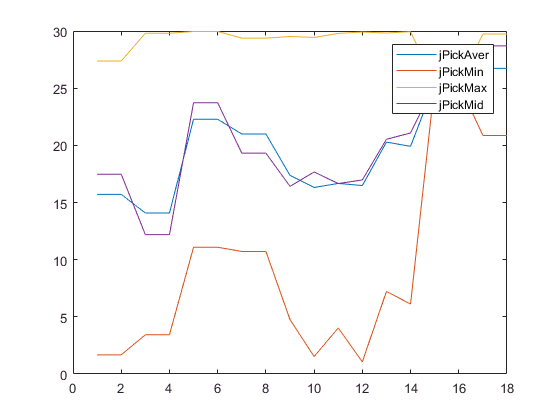

% FileDir = '..\dhx_paper\TEST\Room_810_PCL_0804\Test0_5Hz\';
load([FileDir 'Result.mat'],'Result');
figure
plot(Result([jPickAver jPickMin jPickMax jPickMid],:)')
legend('jPickAver','jPickMin','jPickMax','jPickMid')

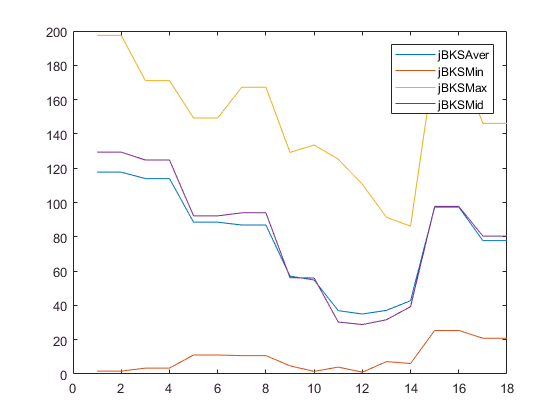

figure
plot(Result([jBKSAver jBKSMin jBKSMax jBKSMid],:)')
legend('jBKSAver','jBKSMin','jBKSMax','jBKSMid')

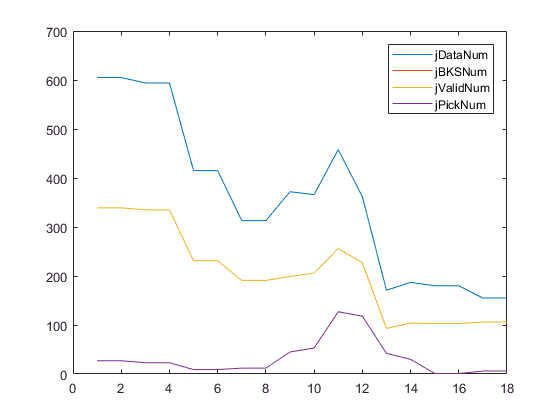

figure
plot(Result([jDataNum jBKSNum jValidNum jPickNum],:)')
legend('jDataNum','jBKSNum','jValidNum','jPickNum')

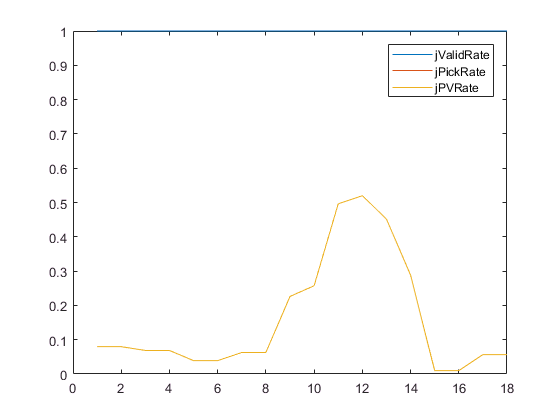

figure
plot(Result([jValidRate jPickRate jPVRate],:)')
legend('jValidRate','jPickRate','jPVRate')

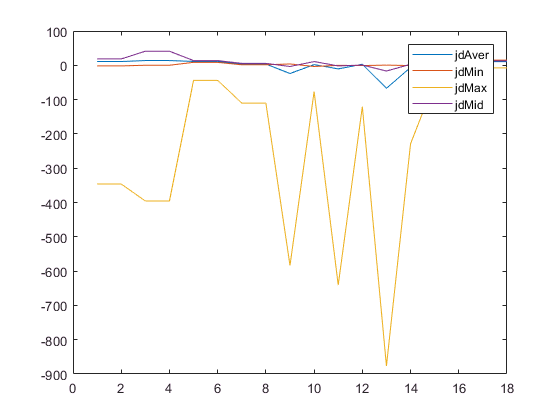


delta = Result([jNBKSAver jNBKSMin jNBKSMax jNBKSMid],:)' -Result([jBKSAver jBKSMin jBKSMax jBKSMid],:)';
figure
plot(delta)
legend('jdAver','jdMin','jdMax','jdMid')

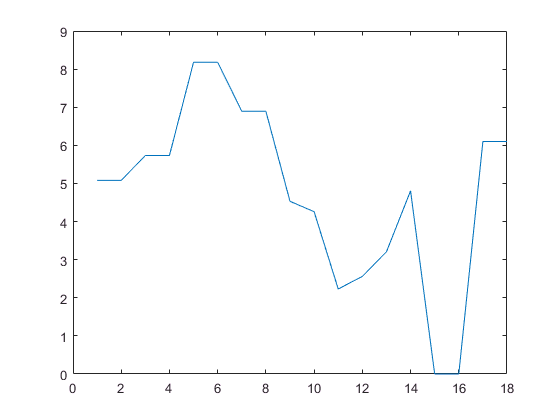

SEM = Result(jPickStd,:)./sqrt(Result(jPickNum,:));            % Standard Error
ts = 1.96;  % 95%
CI_Upper = Result(jPickAver,:) + ts*SEM;                      % Confidence Intervals
CI_lower = Result(jPickAver,:) - ts*SEM;    

CI_delta = CI_Upper - CI_lower;
figure
plot(CI_delta)

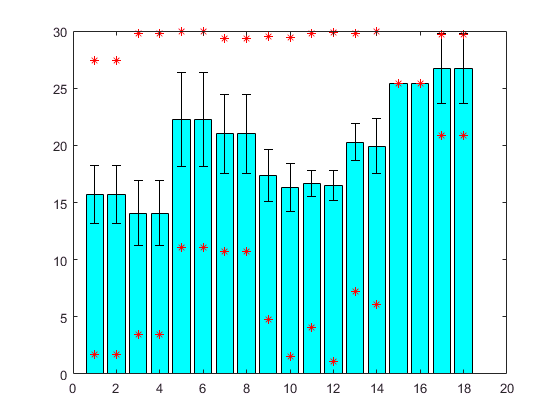


figure
bar(Result(jPickAver,:)','c')
x=1:FileNum;
hold on
errorbar(x,Result(jPickAver,:)', CI_lower' - Result(jPickAver,:)', CI_Upper'-Result(jPickAver,:)','black','Linestyle', 'None');
hold on
plot(x, Result(jPickMax,:)','r*')
hold on
plot(x, Result(jPickMin,:)','r*')

% saveas(gcf, [FileDir 'bar.pdf'], 'pdf')

% % Room_810_PCL_0804
% finalCol = [2 3 6 8 9:14 15 18];
% figure
% bar(Result(jPickAver, finalCol)','c')
% xx=1:CaseNum;
% hold on
% errorbar(xx,Result(jPickAver,finalCol)', CI_lower(finalCol)' - Result(jPickAver,finalCol)', CI_Upper(finalCol)'-Result(jPickAver,finalCol)','black','Linestyle', 'None');
% hold on
% plot(xx, Result(jPickMax,finalCol)','r*')
% hold on
% plot(xx, Result(jPickMin,finalCol)','r*')